## 1.

clear;clc
a = [36 48 87 62 60 52 66 73 73 89 36 12 62 50 60 70 88 90 65]

a =     36    48    87    62    60    52    66    73    73    89    36    12    62    50    60    70    88    90    65


a1 = mean(a)

a1 = 62.0526

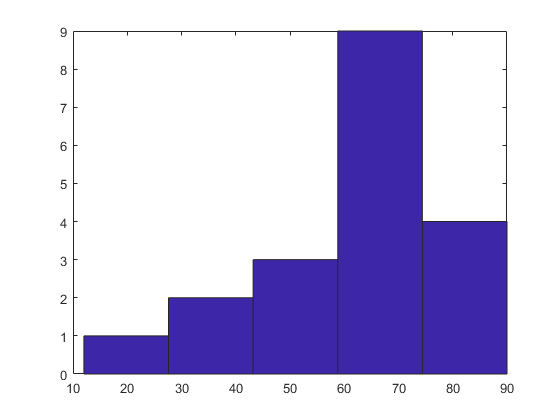

% h = hist(a,5)
hist(a,5)

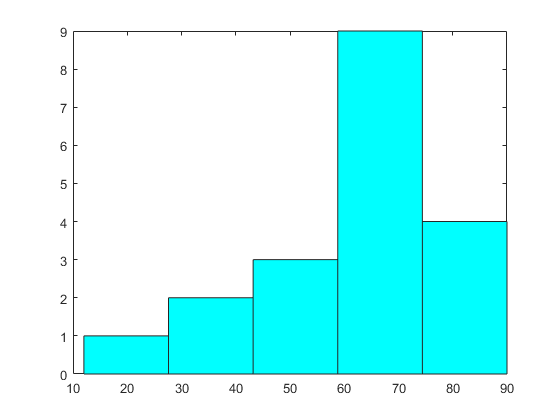

% help hist
h = findobj(gca,'Type','patch');
h.FaceColor = [0 1 1];

## 2.

clear;clc;clf
sp = 138

sp = 138

sm = 187

sm = 187

at = 92

at = 92

wi = 63

wi = 63

% yr = categorical({'春 : 138mm','夏 : 187mm','秋 : 92mm','冬 : 63mm'});
yr = [sp sm at wi]

yr =    138   187    92    63


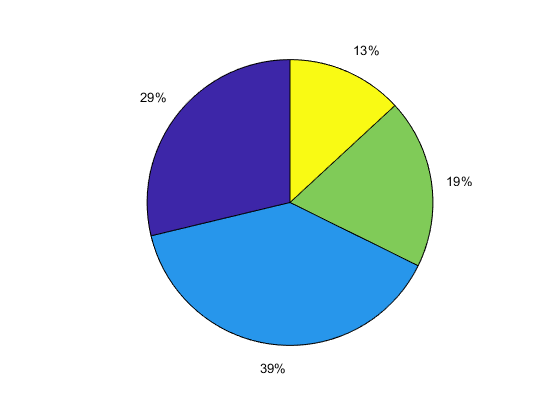

p1 =   1×8 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text 


% figure(1)
p1 = pie(yr)

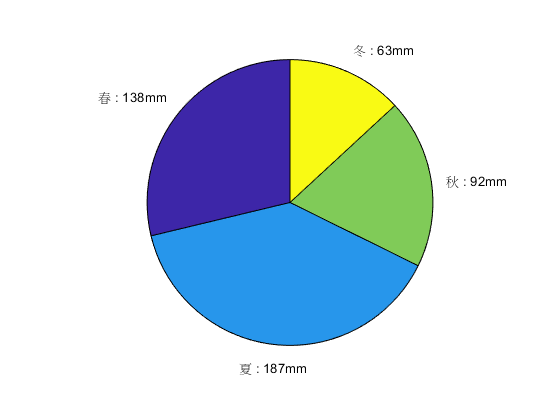

p2 =   1×8 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text 


% figure(2)
p2 = pie(yr,{'春 : 138mm','夏 : 187mm','秋 : 92mm','冬 : 63mm'})

% ,{'春','夏','秋','冬'}
% legend('春 : 138mm','夏 : 187mm','秋 : 92mm','冬 : 63mm','location','best')

## 3.

clear;clc
x = 20

x = 20

ex7_6(x)

exp(x) = 2.712523e+08

## 4.

clear;clc;clf
d = [22 109 116 34.5 240 122;...
    407.1 605 350.5 55.8 596.3 142.8;...
    69 259.5 251.8 49.4 603.4 204;...
    0.1 43 16.5 4.4 310 704.5]

d =    22.0000  109.0000  116.0000   34.5000  240.0000  122.0000
  407.1000  605.0000  350.5000   55.8000  596.3000  142.8000
   69.0000  259.5000  251.8000   49.4000  603.4000  204.0000
    0.1000   43.0000   16.5000    4.4000  310.0000  704.5000


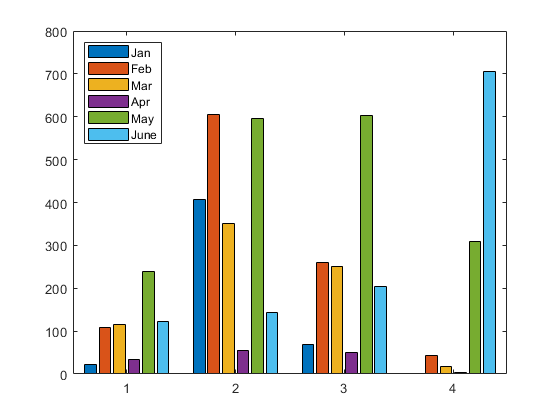

% figure(1)
bar(d)
legend('Jan','Feb','Mar','Apr','May','June','location','northwest')

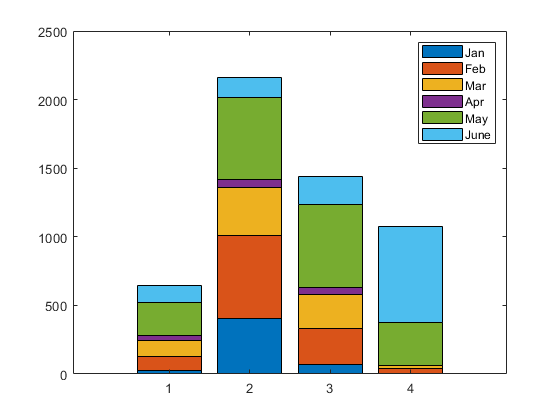

% figure(2)
bar(d,'stacked')
legend('Jan','Feb','Mar','Apr','May','June','location','northeast')

## 5.

clear;clc
bmi(1.79,70);

BMI = 21.847 : 體重標準 


## 6.

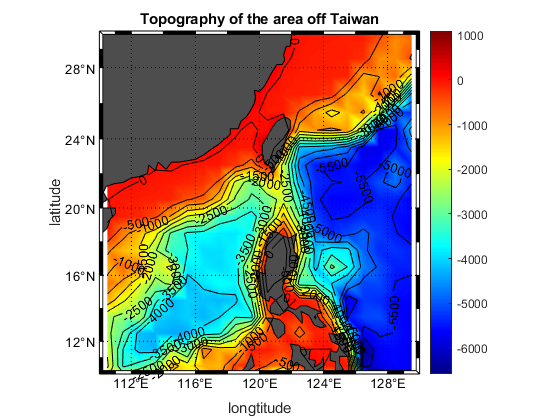

clear;clc;clf
m_proj('Mercator','lon',[110 130],'lat',[10 30]);
m_elev('pcolor');
% m_elev('contourf');
shading interp;
m_coast('patch',[.3 .3 .3]);
colormap('jet');
colorbar('v');
[c,h] = m_elev('contour',[-7000:500:0],'edgecolor','k');
clabel(c,h);
% text(126,20,'Pacific Ocean','color','c','rotation',80)
m_grid('box','fancy');

title('Topography of the area off Taiwan')
xlabel('longtitude');ylabel('latitude')

## 7.

clear;clc;clf
ncdisp("final_exam2020.nc")

Source:
           C:\Users\user\Documents\MATLAB\00781035\final_exam2020.nc
Format:
           classic
Global Attributes:
           title               = 'AVHRR PATHFINDER SEA SURFACE TEMPERATURE'
           temporal_resolution = 'Five Day Average'
           spatial_resolution  = '0.5 degree'
           creation_date       = 'Thu Aug 15 10:40:39 2002'
           originating_center  = 'NASA JPL PO.DAAC'
           WOCE_Version        = '3.0-PF4.1'
           Conventions         = 'COARDS/WOCE'
Dimensions:
           time      = 1
           depth     = 1
           latitude  = 360
           longitude = 720
Variables:
    woce_date
           Size:       1x1
           Dimensions: time
           Datatype:   int32
           Attributes:
                       long_name      = 'WOCE date'
                       units          = 'yyyymmdd'
                       data_min       = 19900101
                       data_max       = 19900105
                       FORTRAN_format = 'I8'
     

lon = ncread('final_exam2020.nc','longitude');
lat = ncread('final_exam2020.nc','latitude');
% time = ncread("final_exam2020.nc",'time')
depth = ncread("final_exam2020.nc",'depth')

depth = single
0

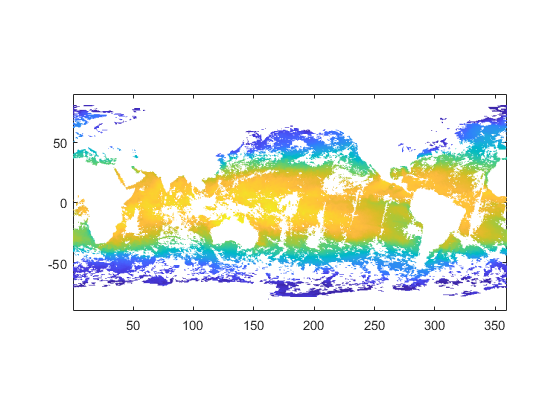

sst = ncread("final_exam2020.nc",'sst');
bin_count = ncread("final_exam2020.nc",'bin_count');

sst(sst >= 327) = nan;

% m_proj('Mercator','lon',[0 360],'lat',[-90,90]);
% m_coast('patch',[.3 .3 .3]);
% m_grid;
[xlat,ylon] = meshgrid(lat,lon);
pcolor(ylon,xlat,sst);shading flat;axis('image');